Lab 05 solutions

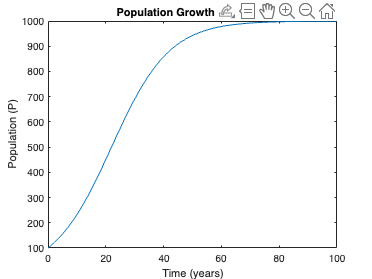


syms P(t);
r = 0.1;
K = 1000;

% Differential equation
dP = diff(P, t);
eqn = dP == r*P*(1 - P/K);
cond = P(0) == 100;

% Solve differential equation
sol = dsolve(eqn, cond);

% Visualization
fplot(sol, [0, 100]);
title('Population Growth over Time');
xlabel('Time (years)');
ylabel('Population (P)');

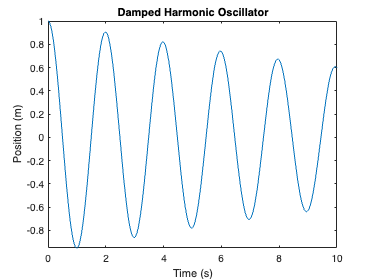

syms x(t);
m = 1;
c = 0.1;
k = 10;

% Differential equation
Dx = diff(x, t);
D2x = diff(x, t, 2);
eqn = m*D2x + c*Dx + k*x == 0;
cond1 = x(0) == 1;
cond2 = Dx(0) == 0;
conds = [cond1 cond2];

% Solve differential equation
sol = dsolve(eqn, conds);

% Visualization
figure;
fplot(sol, [0, 10]);
title('Damped Harmonic Oscillator');
xlabel('Time (s)');
ylabel('Position (m)');